clear all 
Ea = 13.4E10; %elastic modulus ceramic
Em = 210E9; %elastic modulus steel

rho_s = 8,050E3; %kg/m^3

rho_s = 8

rho_a = 7.7E3; %kg/m^3

S0 = 3.3; %micrometers
ha0 = 2E-3; %m

A_a = (15E-3)^2;
A_T = (10E-3)^2;
A_c = (20E-3)^2;



h0 = 50;
h1 = 100;
h_step = 0.1;
h = (h0:h_step:h1)*1E-3;
L1 = length(h)

L1 = 501


La0 = 10;
La1 = 50;
La_step = 0.1;
La = [La0:La_step:La1]*1E-3;
L2 = length(La)

L2 = 401



alpha = zeros(L1,L2);
L_T = zeros(L1,L2);
ia = zeros(L1,L2);
iT = zeros(L1,L2);
S_out = zeros(L1,L2);
Isgood = zeros(L1,L2);
CT = zeros(L1,L2);
Cc = zeros(L1,L2);
Ca = zeros(L1,L2);
Ctot = zeros(L1,L2);

for i=1:L1
    for j=1:L2
        %dimensions 
        alpha(i,j) = atan(h(i)/La(j));
        L_T(i,j) = La(j)/(2*cos( alpha(i,j) ) );
        
        %transmission ratio's
        ia(i,j) = h(i)/La(j);
        iT(i,j) = sin(alpha(i,j));
        
        %output stroke
        S_out(i,j) = ((La(j)/(ia(i,j)*ha0)) - 1) *S0; 
        Isgood(i,j) = (S_out(i,j) >= 7);
        
        %stiffnesses
        CT(i,j) = Em * A_T / L_T(i,j);
        Cc(i,j) = Em * A_c / h(i);
        Ca(i,j) = Ea * A_a / La(j);
        Ctot(i,j) = Cc(i,j) + 0.5*CT(i,j)*iT(i,j) + Ca(i,j)*ia(i,j);
    end
end


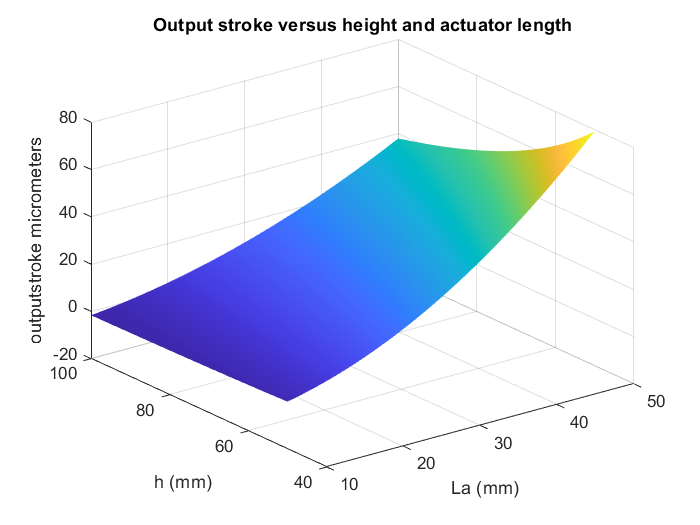

[X,Y] = meshgrid(La0:La_step:La1,h0:h_step:h1);

figure 
clf
s1 = surf(X,Y,S_out);
s1.EdgeColor = 'none';

title('Output stroke versus height and actuator length')
xlabel("La (mm)")
ylabel("h (mm)")
zlabel('outputstroke micrometers')
saveas(gcf,'ssa9/outputstroke.png')

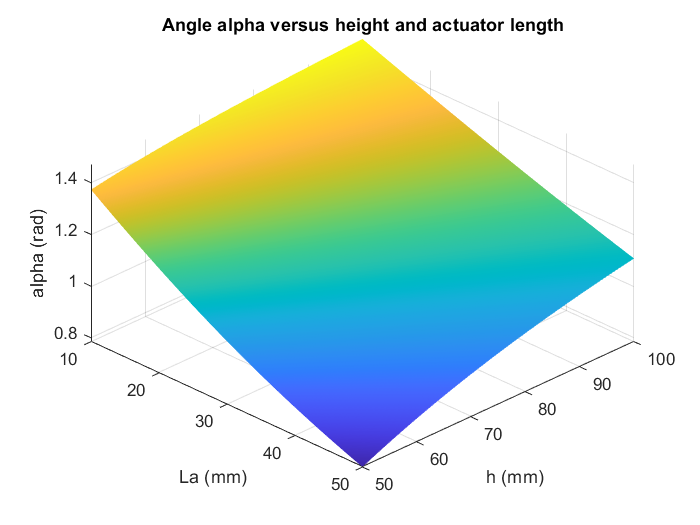



figure 
clf
s1 = surf(X,Y,alpha);
s1.EdgeColor = 'none';

title("Angle alpha versus height and actuator length")
xlabel("La (mm)")
ylabel("h (mm)")
zlabel('alpha (rad)')
view([45 45])
saveas(gcf,'ssa9/alpha.png')


f = figure 

f =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


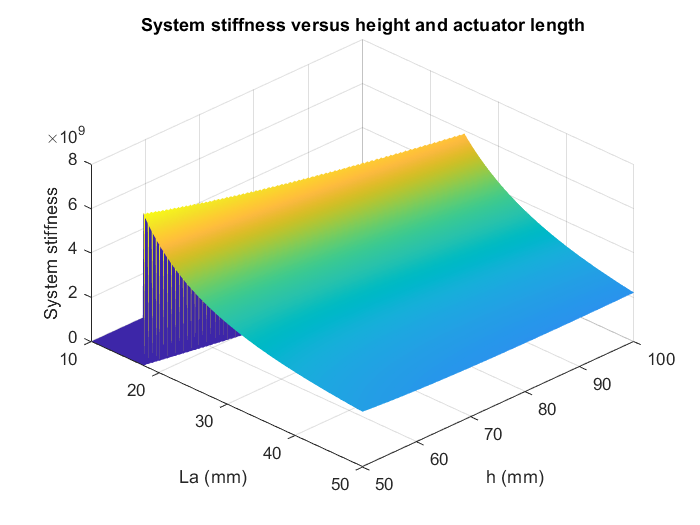

clf
s1 = surf(X,Y,Ctot.*Isgood);
s1.EdgeColor = 'none';

title('System stiffness versus height and actuator length')
xlabel("La (mm)")
ylabel("h (mm)")
zlabel('System stiffness')
view([45 45])
saveas(gcf,'ssa9/systemstiff.png')

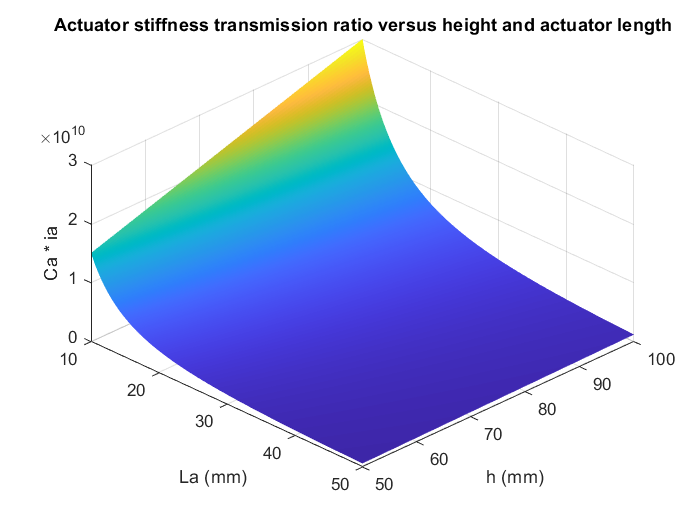


figure 
clf
s1 = surf(X,Y,Ca.*ia);
s1.EdgeColor = 'none';

title("Actuator stiffness transmission ratio versus height and actuator length")
xlabel("La (mm)")
ylabel("h (mm)")
zlabel('Ca * ia')
view([45 45])
saveas(gcf,'ssa9/actuatorstiff.png')

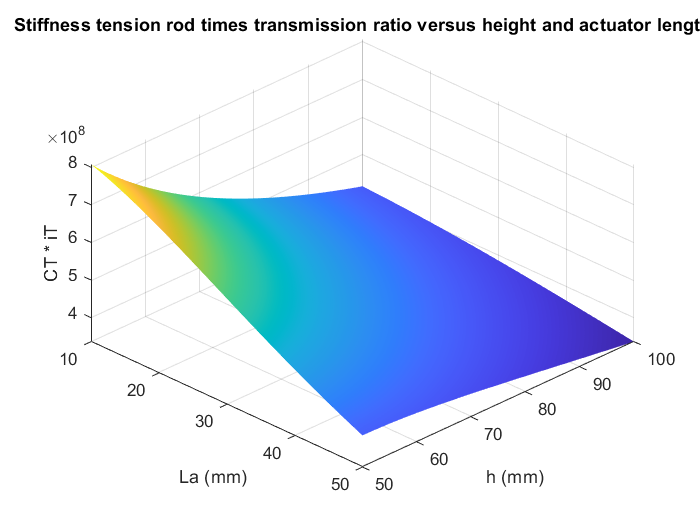


figure 
clf
s1 = surf(X,Y,CT.*iT);
s1.EdgeColor = 'none';

title("Stiffness tension rod times transmission ratio versus height and actuator length")
xlabel("La (mm)")
ylabel("h (mm)")
zlabel('CT * iT')
view([45 45])
saveas(gcf,'ssa9/tensionstiff.png')

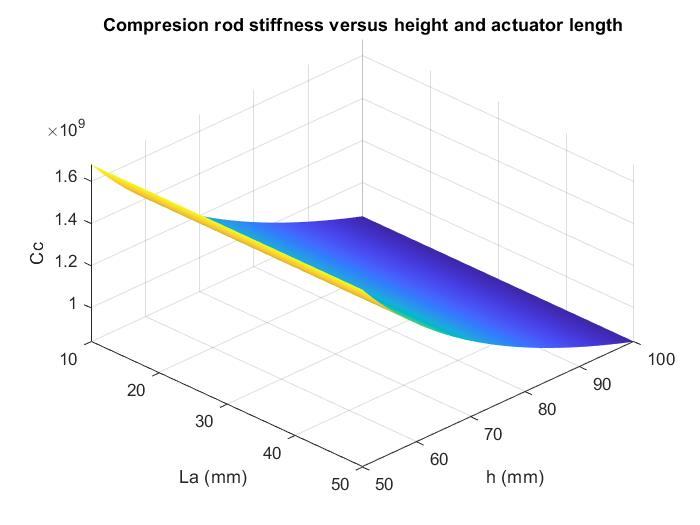


figure 
clf
s1 = surf(X,Y,Cc);
s1.EdgeColor = 'none';

title('Compresion rod stiffness versus height and actuator length')
xlabel("La (mm)")
ylabel("h (mm)")
zlabel('Cc')
view([45 45])
saveas(gcf,'ssa9/compresionstiff.png')